# Behavioural model equilibrium and stability analysis

Initialization 

addpath(genpath('..\'))
obj = functionsContainer;
x = linspace(0,1,1000);
y = linspace(0,1,20);
fig = 0;

There are several different equilibrium possible, based on the parameters reciprocal relations. In the following sections are presented and their stability is also verified. 

## Caso B1 <1 and B2 < 1

B1 = 0.89;
B2 = 0.45;
lambda_1 = 1/30; %fatigue to mantain C behaviour
lambda_2 = 1/40; %fatigue to mantain A behaviour
k1 = B1*lambda_1 ; %from H to C
k2 = B2*lambda_2; %from H to A


Definition of system equations

syms H C A 

eq_H(H,C) = -k1*H*C - k2*(1-H-C)*H + lambda_1*C + lambda_2 * (1-H-C);
eq_C(H,C) = +k1*H*C - lambda_1*C;

Simulation and printing the result with this condition. 

time = 500;
%
C_zero = 20e6;
A_zero = 20e6;
[taxisRK,HaxisRK,CaxisRK,AaxisRK,awareness] = obj.Behaviour_RK_ic(k1,k2,lambda_1,lambda_2,time,C_zero, A_zero);

fig = fig+1;
figure(fig)
hold on
plot(taxisRK,HaxisRK, 'linewidth',1.4 )
plot(taxisRK,CaxisRK, 'linewidth',1.4 )
plot(taxisRK,AaxisRK, 'linewidth',1.4 )
xlabel("t[days]");
ylabel("H[t], C[t], A[t]");
ylim([0,1])
legend('Heedless', 'Compliant', 'Against', Orientation='horizontal', Location='southoutside')
txt = {['B_1=' num2str(B1)], ['B_2=' num2str(B2)], ['k_1=' num2str(round(k1,2))],['k_2=' num2str(round(k2,2))],['\lambda_1=' num2str(round(lambda_1,2))],['\lambda_2=' num2str(round(lambda_2,2))]};    
dim = [.91 .8 .1 .1];
annotation('textbox',dim, ...
    'String',txt,'EdgeColor','none')
fontsize(20,"points")
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 23 15]);
set(gcf, 'PaperSize', [24 15]); % dimension on x axis and y axis resp.


Plot of the nullclines

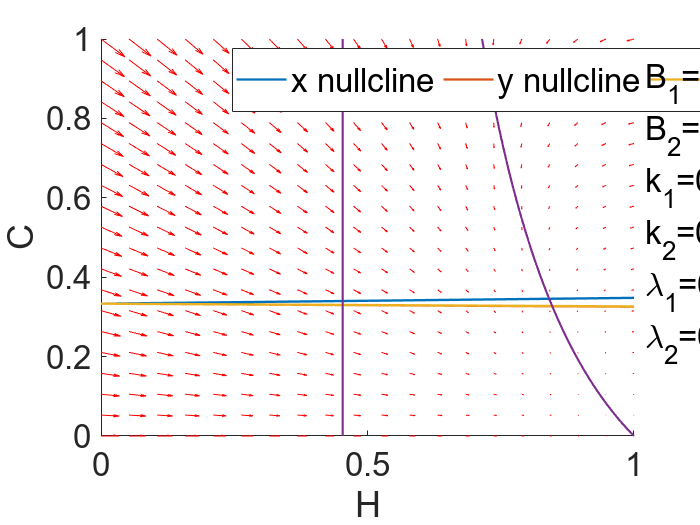

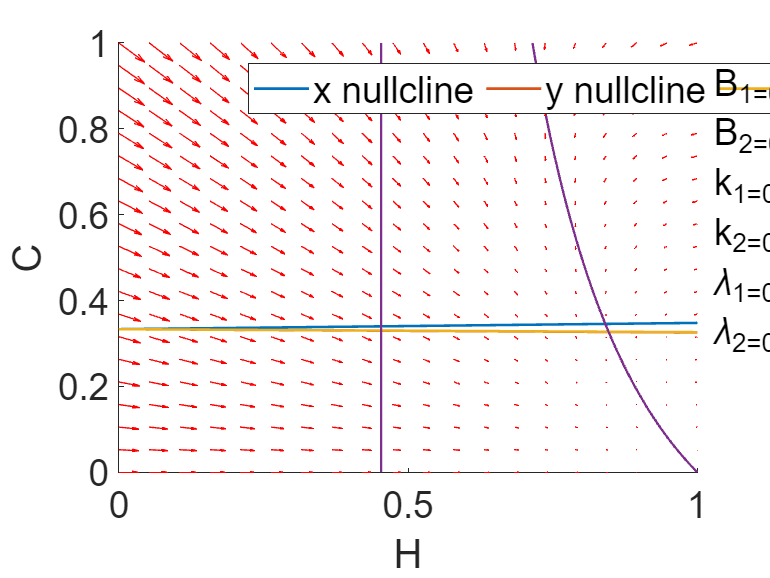

% Calculation of system vector field 
u = zeros(length(y), length(y));
v = zeros(length(y), length(y));
for i = 1:numel(y)
    for j = 1:numel(y)
        u(i,j) = eq_H(y(i),y(j));
        v(i,j) = eq_C(y(i),y(j));
    end
end
u2 = u; u2 = transpose(u2);
v2 = v; v2 = transpose(v2);

% figure
fig = fig+1;
figure(fig)
hold on
plot(x,x_nullcline(x,k1,k2,lambda_1,lambda_2), LineWidth=1.3)
xline((lambda_1/k1), LineWidth= 1.3)
quiver(y,y,u2,v2,'r')
xlabel("H")
ylabel("C")
legend('x nullcline', 'y nullcline', 'vector field')
hold off
xlim([0 1])
ylim([0 1])
legend("Position", [0.66855,0.7858,0.23349,0.12348])

Jacobian calculation

% The Jacobian of this equation in this case is:
Jac(H, C) = jacobian([eq_H, eq_C], [H, C])

$$Jac(H, C) = \left(\begin{array}{cc} \frac{9\,H}{400}-\frac{221\,C}{12000}-\frac{29}{800} & \frac{1}{120}-\frac{221\,H}{12000}\\ \frac{89\,C}{3000} & \frac{89\,H}{3000}-\frac{1}{30} \end{array}\right)$$

Computation of Jacobian trace and determinant:

% Computing the Trace
Trac(H,C) = trace(Jac(H,C))

$$Trac(H, C) = \frac{313\,H}{6000}-\frac{221\,C}{12000}-\frac{167}{2400}$$

% Determinant
d(H,C) = det(Jac)

$$d(H, C) = \frac{267\,H^{2}}{400000}-\frac{4381\,H}{2400000}+\frac{11\,C}{30000}+\frac{29}{24000}$$

Substituting the equilibrium value in the trace and determinant to see if the equilibrium satisfies Routh-Hurwitz conditon:

- trace(J) < 0

- det(J) > 0

In this case the value of equilibrium correspond to H = 1 and C =0.

value1 = 1;
value2 =  0;
trace_J = Trac(value1, value2)

$$trace\_J = -\frac{209}{12000}$$


det_J =  d(value1, value2)

$$det\_J = \frac{121}{2400000}$$

Both conditions are satisifed. The equilibrium is  asymptotically stable. 

## Caso E1 > E2 and E1 > 1

% Simulation parameters
E1 = 1.5;
E2 = 1.2;
k1 =  1/2.05; %from Ca to Co
k2 = 1/2; %from C to Ag
lambda_1 = k1/E1; %fatigue to mantain Co behaviour
lambda_2 = k2/E2; %fatigue to mantain Ag behaviour

Simulation and printing the result with this condition. 

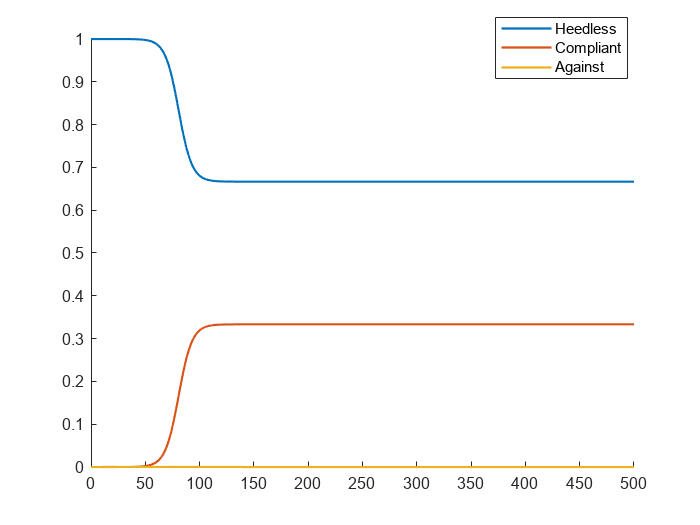

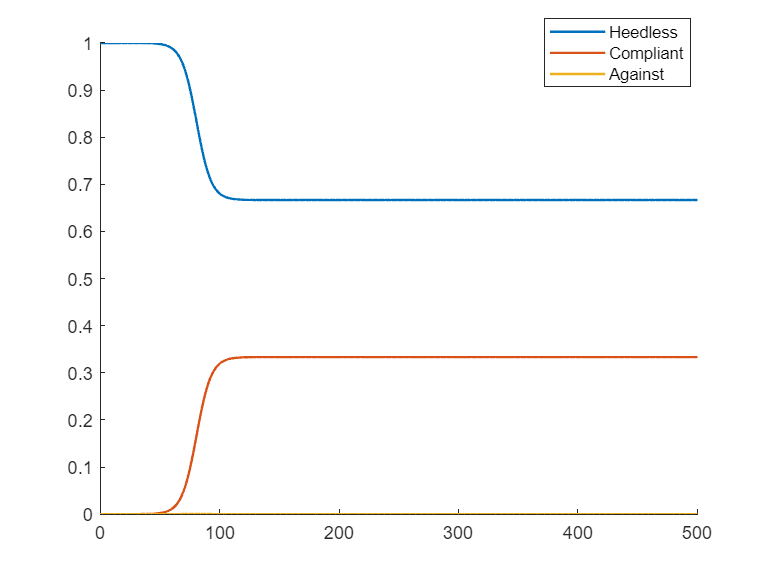

time = 500;
C_zero = 40;
A_zero = 40;
[taxisRK,xaxisRK,yaxisRK,zaxisRK,awareness] = obj.Behaviour_RK_ic(k1,k2,lambda_1,lambda_2,time,C_zero, A_zero);

fig = fig+1;
figure(fig)
hold on
plot(taxisRK,xaxisRK, 'linewidth',1.3 )
plot(taxisRK,yaxisRK, 'linewidth',1.3 )
plot(taxisRK,zaxisRK, 'linewidth',1.3 )
legend('Heedless', 'Compliant', 'Against')
xlim([0 500])
ylim([0.000 1.000])
legend("Position", [0.70777,0.8488,0.18929,0.11905])
hold off

Plot of the nullclines

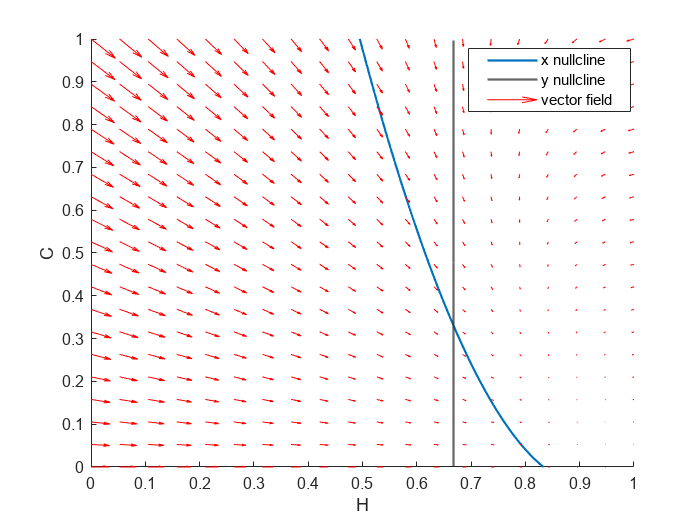

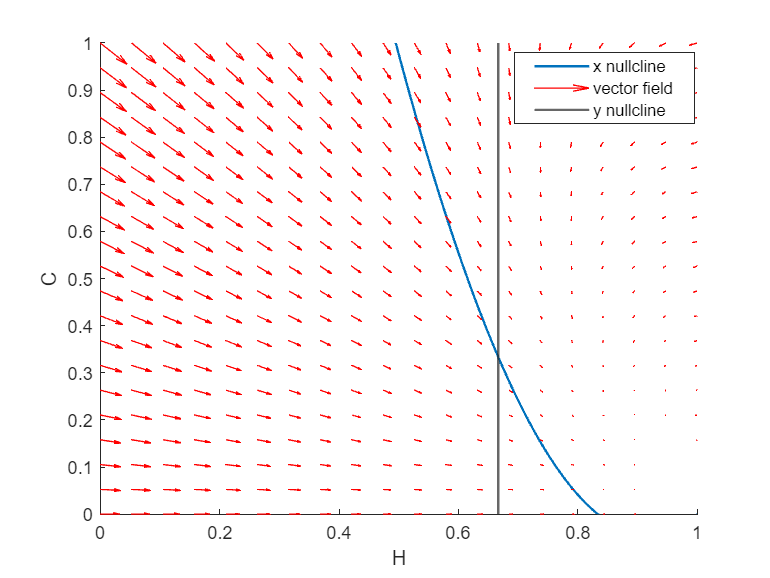

% Calculation of system vector field 
u = zeros(length(y), length(y));
v = zeros(length(y), length(y));
for i = 1:numel(y)
    for j = 1:numel(y)
        u(i,j) = eq_H(y(i),y(j));
        v(i,j) = eq_C(y(i),y(j));
    end
end
u2 = u; u2 = transpose(u2);
v2 = v; v2 = transpose(v2);

% figure
fig = fig+1;
figure(fig)
hold on
plot(x,x_nullcline(x,k1,k2,lambda_1,lambda_2), LineWidth=1.3)
xline((lambda_1/k1), LineWidth= 1.3)
quiver(y,y,u2,v2,'r')
xlabel("H")
ylabel("C")
legend('x nullcline', 'y nullcline', 'vector field')
hold off
xlim([0 1])
ylim([0 1])
legend("Position", [0.66855,0.7858,0.23349,0.12348])

Definition of system equation and Jacobian calculation

syms H C A

eq_H(H,C) = -k1*H*C - k2*(1-H-C)*H + lambda_1*C + lambda_2 * (1-H-C);
eq_C(H,C) = +k1*H*C - lambda_1*C;

% The Jacobiana of this equation in this case is:
Jac(H, C) = jacobian([eq_H, eq_C], [H, C])

$$Jac(H, C) = \left(\begin{array}{cc} \frac{C}{82}+H-\frac{11}{12} & \frac{H}{82}-\frac{15}{164}\\ \frac{20\,C}{41} & \frac{20\,H}{41}-\frac{40}{123} \end{array}\right)$$

Computation of Jacobian trace and determinant:

% Computing the Trace
Trac(H,C) = trace(Jac(H,C))

$$Trac(H, C) = \frac{C}{82}+\frac{61\,H}{41}-\frac{611}{492}$$

% Determinant
d(H,C) = det(Jac)

$$d(H, C) = \frac{20\,H^{2}}{41}-\frac{95\,H}{123}+\frac{5\,C}{123}+\frac{110}{369}$$

Substituting the equilibrium value in the trace and determinant to see if the equilibrium satisfies Routh-Hurwitz conditon:

- trace(J) < 0

- det(J) > 0

The value at equilibrium in this case can be found using the formula H = $\lambda_1 / k1$ and C = 1-$\lambda_1 / k1$   

value1 = lambda_1/k1; 
value2 =  (1-lambda_1/k1);
trace_J = Trac(value1, value2)

$$trace\_J = -\frac{121}{492}$$

det_J =  d(value1, value2)

$$det\_J = \frac{5}{369}$$

Both conditions are satisifed. The equilibrium is  asymptotically stable. 

## Caso E1 = E2

% Simulation parameters
E1 = 1.2;
E2 = 1.2;
k1 =  1/2.05 %from H to C

k1 = 0.4878

k2 = 1/2 %from H to A

k2 = 0.5000

lambda_1 = k1/E1 %fatigue to mantain C behaviour

lambda_1 = 0.4065

lambda_2 = k2/E2 %fatigue to mantain A behaviour

lambda_2 = 0.4167

Simulation and printing the result with this condition. In this case there is an equilibrium visible from the evolution of the system, but its value cannot  be directly calculated with the method used before. In fact the initial conidtions have an impact on the final value reached by the system at equilibrium. Furthermore the nullcline plot show an intersection in an area that cannot exist, because is out of the existence condition of the parameters. 

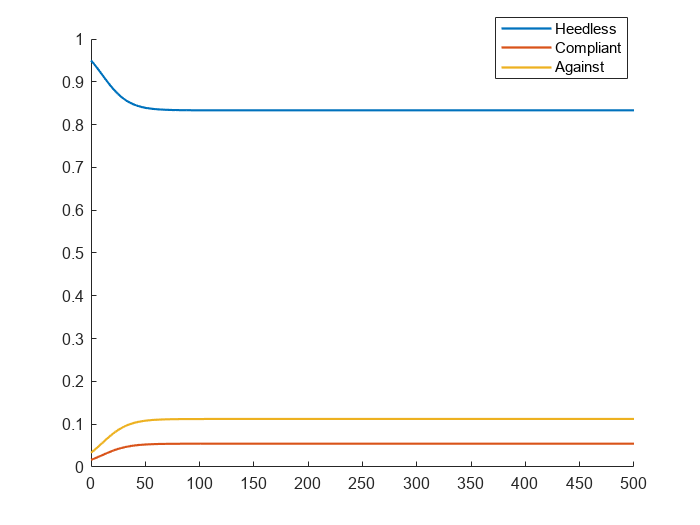

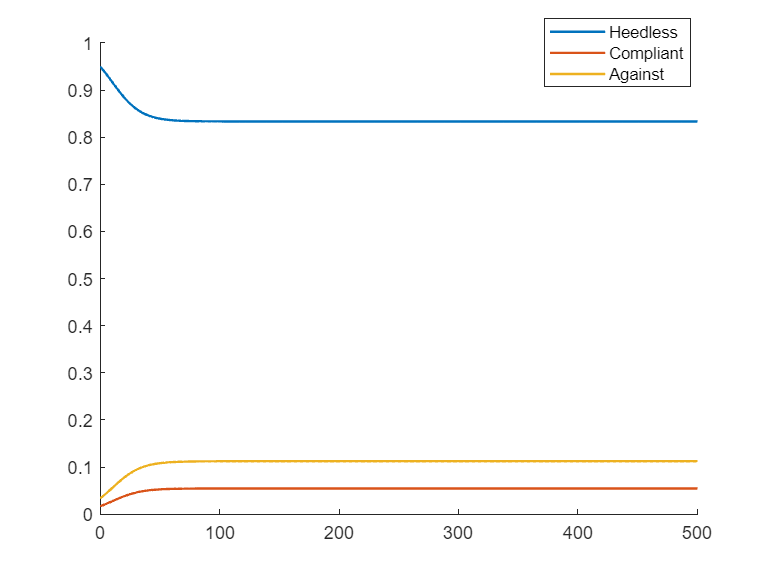

time = 500;
C_zero = 10e5;
A_zero = 20e5;
[taxisRK2,xaxisRK2,yaxisRK2,zaxisRK2,awareness2] = obj.Behaviour_RK_ic(k1,k2,lambda_1,lambda_2,time,C_zero, A_zero);
  
fig = fig+1;
figure(fig)
hold on
plot(taxisRK2,xaxisRK2, 'linewidth',1.3 )
plot(taxisRK2,yaxisRK2, 'linewidth',1.3 )
plot(taxisRK2,zaxisRK2, 'linewidth',1.3 )
legend('Heedless', 'Compliant', 'Against')
xlim([0 500])
ylim([0.000 1.000])
hold off
legend("Position", [0.70777,0.8488,0.18929,0.11905])

Plot of the nullclines

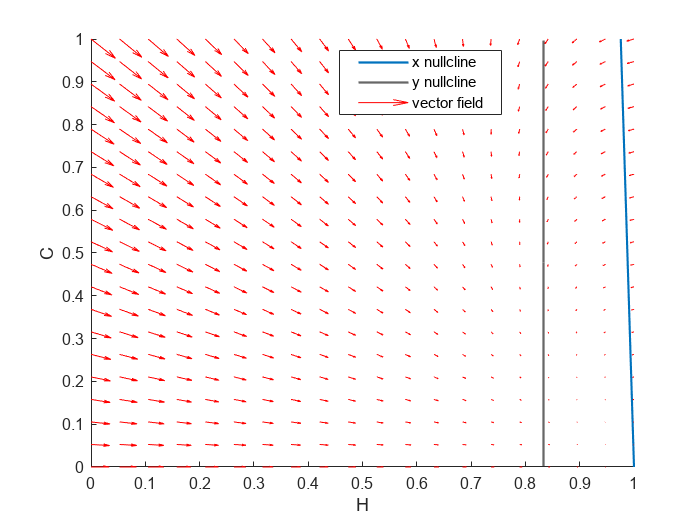

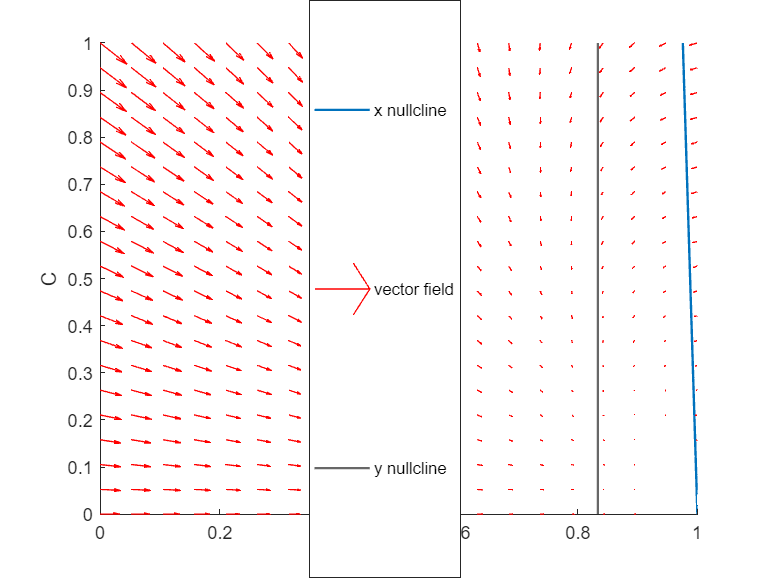

%%  Calculation of system vector field 
% Calculation of system vector field 
uu = zeros(length(y), length(y));
vu = zeros(length(y), length(y));
for ii = 1:numel(y)
    for jj = 1:numel(y)
        uu(ii,jj) = eq_H(y(ii),y(jj));
        vu(ii,jj) = eq_C(y(ii),y(jj));
    end
end
u2 = u; u2 = transpose(u2);
v2 = v; v2 = transpose(v2);

% figure
fig = fig+1;
figure(fig)
hold on
plot(x,x_nullcline(x,k1,k2,lambda_1,lambda_2), LineWidth=1.3)
xline((lambda_1/k1), LineWidth= 1.3)
quiver(y,y,u2,v2,'r')
xlabel("H")
ylabel("C")
legend('x nullcline', 'y nullcline', 'vector field')
hold off
xlim([0 1])
ylim([0 1])
legend("Position", [0.48413,0.78061,0.23349,0.12348])

Definition of system equation and Jacobian calculation

syms H C A

eq_H(H,C) = -k1*H*C - k2*(1-H-C)*H + lambda_1*C + lambda_2 * (1-H-C);
eq_C(H,C) = +k1*H*C - lambda_1*C;

% The Jacobiana of this equation in this case is:
Jac(H, C) = jacobian([eq_H, eq_C], [H, C])

$$Jac(H, C) = \left(\begin{array}{cc} \frac{C}{82}+H-\frac{11}{12} & \frac{H}{82}-\frac{5}{492}\\ \frac{20\,C}{41} & \frac{20\,H}{41}-\frac{50}{123} \end{array}\right)$$

Computation of Jacobian trace and determinant:

% Computing the Trace
Trac(H,C) = trace(Jac(H,C))

$$Trac(H, C) = \frac{C}{82}+\frac{61\,H}{41}-\frac{217}{164}$$

% Determinant
d(H,C) = det(Jac)

$$d(H, C) = \frac{20\,H^{2}}{41}-\frac{35\,H}{41}+\frac{275}{738}$$

Substituing the equilibrium value in the trace and determinat to see if the equilibrium satisfies Routh-Hurwitz conditon:

- trace(J) < 0

- det(J) > 0

In this particular case the value of the Careless can be calculated with two different formula: H = $\lambda_1/k1$ or C = $\lambda_2/k2$

There is not an expression to find the value of the Compliant and Against compartment. It depends on the initial condition, the value of Co(0) and Ag(0) at the beginning of the simulation. Also, the trace depends on both the unkowns Ca and Co, while the determinant is a function of Ca only, but at the equilibrium is value is zero. In this case anything can be said about the stability of the equilibrium. 

value1 = lambda_1/k1; 
value2 =  (1-lambda_1/k1);
trace_J = Trac(value1, value2)

$$trace\_J = -\frac{10}{123}$$


det_J =  d(value1, value2)

$$det\_J = 0$$

## Caso E2 > E1 and E2 > 1

% Simulation parameters
E1 = 1.2;
E2 = 1.9;
k1 =  1/4; %from H to C 
k2 = 1/5; %from H to A
lambda_1 = k1/E1; %fatigue to mantain Co behaviour
lambda_2 = k2/E2; %fatigue to mantain Ag behaviour

Simulation and printing the result with this   condition. 

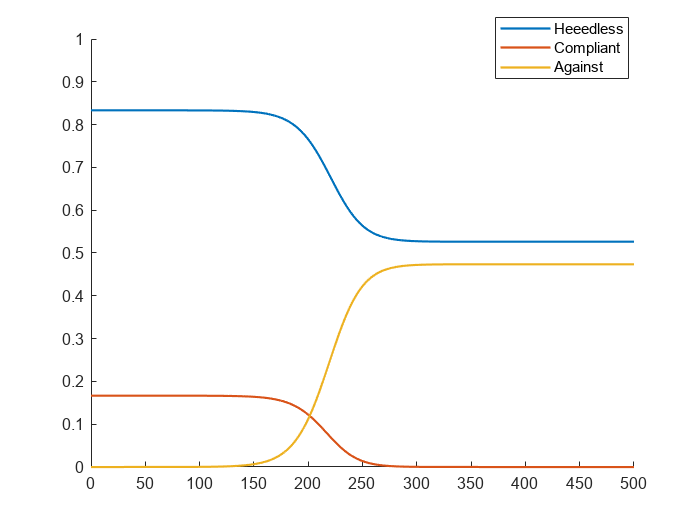

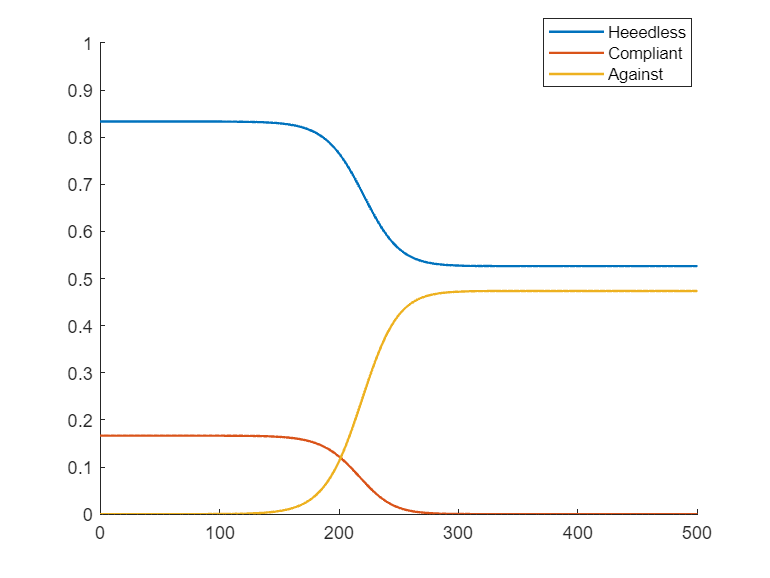

time = 500;
C_zero = 10e6;
A_zero = 40;
[taxisRK,xaxisRK,yaxisRK,zaxisRK,awareness] = obj.Behaviour_RK_ic(k1,k2,lambda_1,lambda_2,time,C_zero, A_zero);

fig = fig+1;
figure(fig)
hold on
plot(taxisRK,xaxisRK, 'linewidth',1.3 )
plot(taxisRK,yaxisRK, 'linewidth',1.3 )
plot(taxisRK,zaxisRK, 'linewidth',1.3 )
legend('Heeedless', 'Compliant', 'Against')
xlim([0 500])
ylim([0.000 1.000])
legend("Position", [0.70777,0.8488,0.18929,0.11905])
hold off

Plot of the nullclines

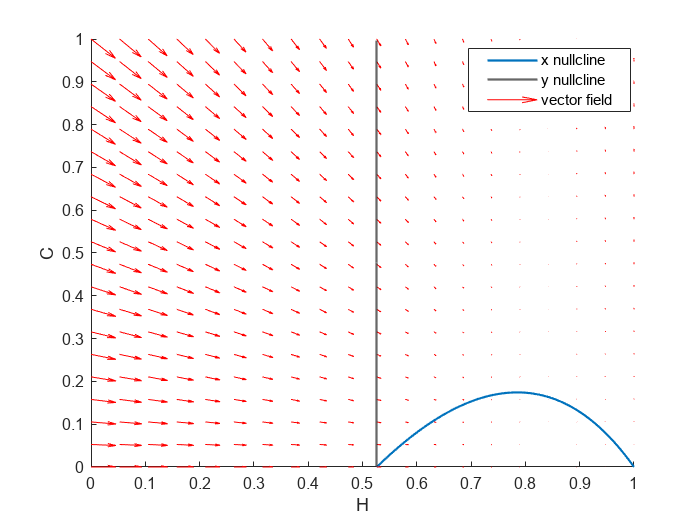

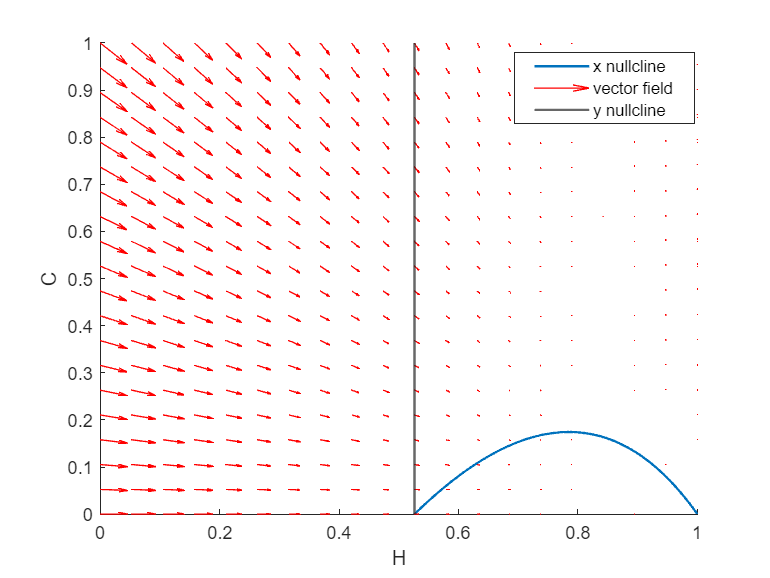

% Calculation of system vector field 
u = zeros(length(y), length(y));
v = zeros(length(y), length(y));
for i = 1:numel(y)
    for j = 1:numel(y)
        u(i,j) = eq_H(y(i),y(j));
        v(i,j) = eq_C(y(i),y(j));
    end
end
u2 = u; u2 = transpose(u2);
v2 = v; v2 = transpose(v2);

% figure
fig = fig+1;
figure(fig)
hold on
plot(x,x_nullcline(x,k1,k2,lambda_1,lambda_2), LineWidth=1.3)
xline((lambda_2/k2), LineWidth= 1.3)
quiver(y,y,u2,v2,'r')
xlabel("H")
ylabel("C")
legend('x nullcline', 'y nullcline', 'vector field')
hold off
xlim([0 1])
ylim([0 1])
legend("Position", [0.66855,0.7858,0.23349,0.12348])

Another nullcline plot is here showed. It is the one obtained solving a different system of equation, the Careless/Against ones. Its shape in this case corresponds to the one visible in the case R1 >R2 and R1 >1.

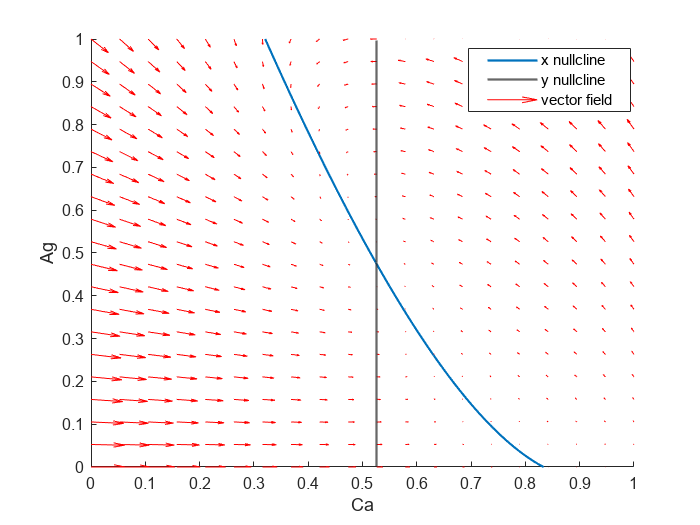

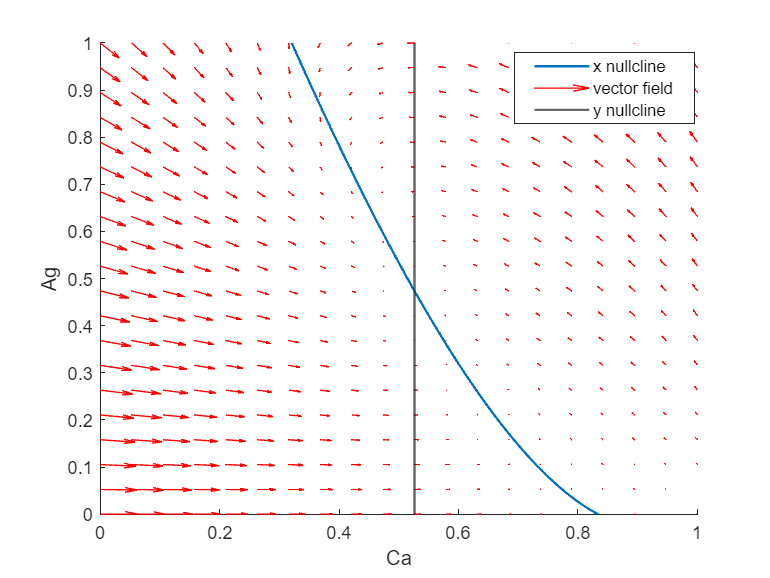

eq_H(H,A) = -k1*H*(1-H-A) - k2*A*H + lambda_1*(1-H-A) + lambda_2 * A;
eq_Ag(H,A) = +k2*H*A - lambda_2*A;
% Calculation of system vector field 
u = zeros(length(y), length(y));
v = zeros(length(y), length(y));
for i = 1:numel(y)
    for j = 1:numel(y)
        u(i,j) = eq_H(y(i),y(j));
        v(i,j) = eq_Ag(y(i),y(j));
    end
end
u2 = u; u2 = transpose(u2);
v2 = v; v2 = transpose(v2);

% figure
fig = fig+1;
figure(fig)
hold on
plot(x,y_nullcline(x,k1,k2,lambda_1,lambda_2), LineWidth=1.3)
xline((lambda_2/k2), LineWidth= 1.3)
quiver(y,y,u2,v2,'r')
xlabel("Ca")
ylabel("Ag")
legend('x nullcline', 'y nullcline', 'vector field')
hold off
xlim([0 1])
ylim([0 1])
legend("Position", [0.66855,0.7858,0.23349,0.12348])

Another possible nullcline plot. In this case the one obtained solving the system Complaint-Against. In this case the nullclines are two parallel lines. The one that is above represent the "dominant" groupm because has the large reproduction rate.  The only possible stable equilibrium in this case is the one corresponding to the point of the second nullcline in which Co = 0. 

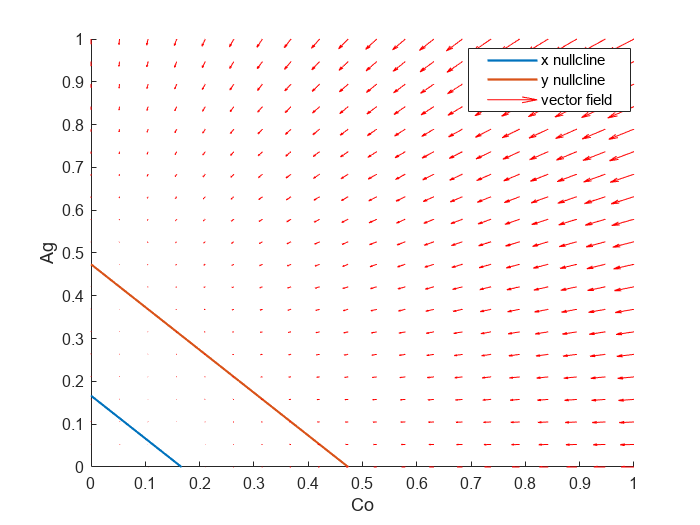

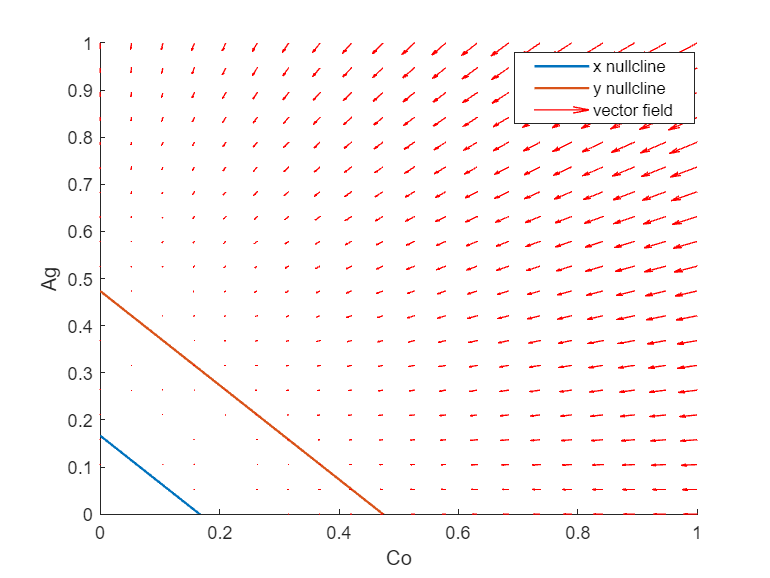

eq_Co2(C, A) = +k1*(1-C-A)*C - lambda_1*C;
eq_Ag2(C, A) = +k2*(1-C-A)*A - lambda_2*A;

% Calculation of system vector field 
u = zeros(length(y), length(y));
v = zeros(length(y), length(y));
for i = 1:numel(y)
    for j = 1:numel(y)
        u(i,j) = eq_Co2(y(i),y(j));
        v(i,j) = eq_Ag2(y(i),y(j));
    end
end
u2 = u; u2 = transpose(u2);
v2 = v; v2 = transpose(v2);

% figure
fig = fig+1;
figure(fig)
hold on
plot(x,x_nullcline2(x,k1,k2,lambda_1,lambda_2), LineWidth=1.3)
plot(x,y_nullcline2(x,k1,k2,lambda_1,lambda_2), LineWidth=1.3)
quiver(y,y,u2,v2,'r')
xlabel("Co")
ylabel("Ag")
legend('x nullcline', 'y nullcline', 'vector field')
hold off
xlim([0 1])
ylim([0 1])
legend("Position", [0.66855,0.7858,0.23349,0.12348])

Definition of system equation and Jacobian calculation

syms H C A

eq_H(H,A) = -k1*H*(1-H-A) - k2*A*H + lambda_1*(1-H-A) + lambda_2 * A;
eq_C(H,C) = +k1*H*C - lambda_1*C;
eq_Ag(H,A) = +k2*H*A - lambda_2*A;

% The Jacobiana of this equation in this case is:

Jac(H, A) = jacobian([eq_H, eq_Ag], [H, A])

$$Jac(H, A) = \left(\begin{array}{cc} \frac{A}{20}+\frac{H}{2}-\frac{11}{24} & \frac{H}{20}-\frac{47}{456}\\ \frac{A}{5} & \frac{H}{5}-\frac{2}{19} \end{array}\right)$$

Computation of Jacobian trace and determinant:

% Computing the Trace
Trac(H,A) = trace(Jac(H,A))

$$Trac(H, A) = \frac{A}{20}+\frac{7\,H}{10}-\frac{257}{456}$$

% Determinant
d(H,A) = det(Jac)

$$d(H, A) = \frac{H^{2}}{10}-\frac{329\,H}{2280}+\frac{7\,A}{456}+\frac{11}{228}$$

Substituting the equilibrium value in the trace and determinant to see if the equilibrium satisfies Routh-Hurwitz conditon:

- trace(J) < 0

- det(J) > 0

The value at equilibrium in this case can be found using the formula Ca = $\lambda_1 / k1$ and Co = 1-$\lambda_1 / k1$   

value1 = lambda_2/k2; 
value2 =  (1-lambda_2/k2);
trace_J = Trac(value1, value2)

$$trace\_J = -\frac{391}{2280}$$


det_J =  d(value1, value2)

$$det\_J = \frac{21}{2888}$$

Both conditions are satisifed. The equilibrium is  asymptotically stable.

## Sensitivity analysis

Now are plotted some results obtained from the simulations of the behavioural model

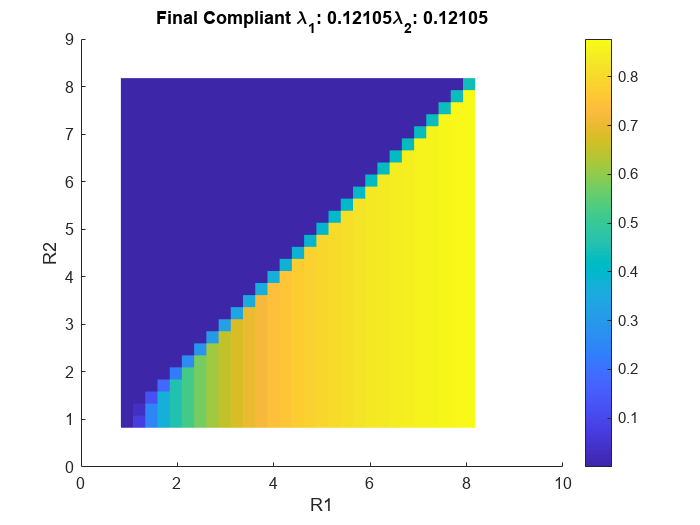

 load("..\data/multilpiBehaviour.mat")
 k1_vec = linspace(0.1, 0.99,30);
lam1_vec = linspace(1/5, 1/30, 20);
vec_R2 = [2,5,8,12,16,19]; % six values to calculated R2

%% Equilibrium plot of R1 and R2
fig = fig+1;
figure(fig)
%1,1
d1 = 10; d2 = 10;
fig = fig+1;
figure(fig)
r1 = k1_vec./lam1_vec(d1);
r2 = k1_vec./lam1_vec(d2);
[xx, yy] = meshgrid(r1,r2);
aga = reshape(final_Co(:,:,d1,d2),30,30,[]);
zz = aga; zz = transpose(zz);
surface(xx,yy,zz, 'edgecolor','none')
colorbar;
colormap default;
txt3 = "Final Compliant "+ '\lambda_1: '+ num2str(lam1_vec(d1)) +'\lambda_2: '+ num2str(lam1_vec(d2));
title(txt3)
xlabel('R1') 
ylabel('R2') 

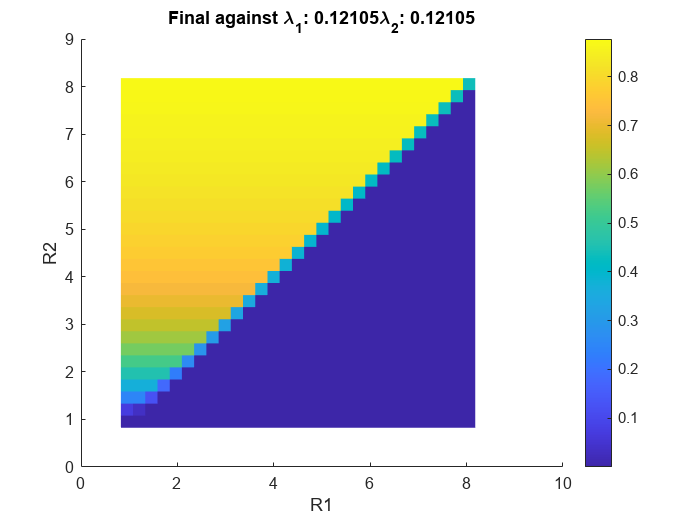

% 1,2
fig = fig+1;
figure(fig)
r1 = k1_vec./lam1_vec(d1);
r2 = k1_vec./lam1_vec(d2);
[xx, yy] = meshgrid(r1,r2);
aga = reshape(final_Ag(:,:,d1,d2),30,30,[]);
zz = aga; zz = transpose(zz);
surface(xx,yy,zz, 'edgecolor','none')
colorbar;
colormap default;
txt3 = "Final against "+ '\lambda_1: '+ num2str(lam1_vec(d1)) +'\lambda_2: '+ num2str(lam1_vec(d2));
title(txt3)
xlabel('R1') 
ylabel('R2') 

These first two plots are the final value at equilibrium of Compliant and Against compartments. The Careless one is in the next figure.

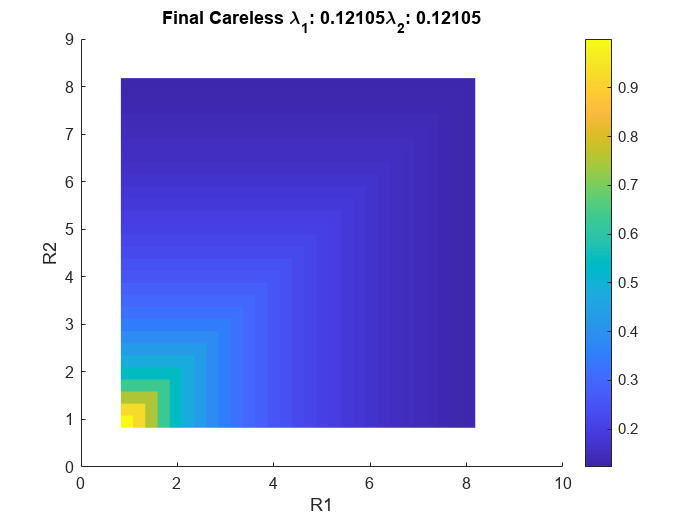

% Careless at equilibrium
fig = fig+1;
figure(fig)
r1 = k1_vec./lam1_vec(d1);
r2 = k1_vec./lam1_vec(d2);
[xx, yy] = meshgrid(r1,r2);
aga = reshape(final_Ca(:,:,d1,d2),30,30,[]);
zz = aga; zz = transpose(zz);
surface(xx,yy,zz, 'edgecolor','none')
colorbar;
colormap default;
txt3 = "Final Careless "+ '\lambda_1: '+ num2str(lam1_vec(d1)) +'\lambda_2: '+ num2str(lam1_vec(d2));
title(txt3)
xlabel('R1') 
ylabel('R2') 

The final plots are done to show the final system values as a variation of R1 parameter only.

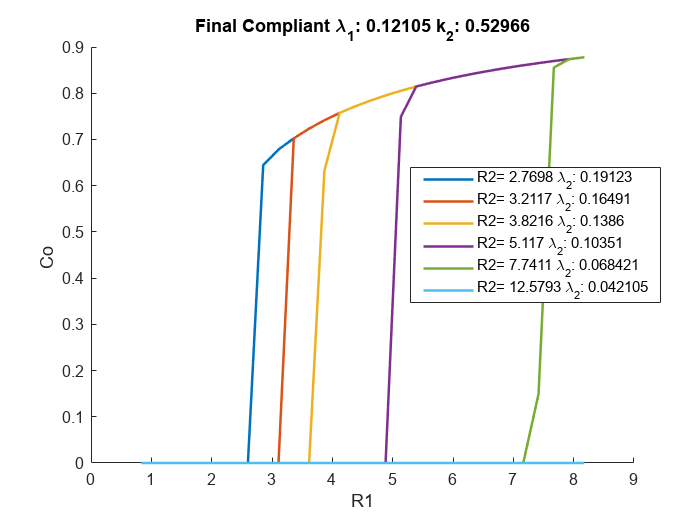

%% Equilibrium value function of R1
fig = fig+1;
figure(fig)
%1,1
d1 = 10; d3 = 15;
nexttile
hold on
r1 = k1_vec./lam1_vec(d1);
for i = 1:6
    d2 = vec_R2(i);
    aga = reshape(final_Co(:,d3,d1,d2),1,30,[]);
    zz = aga; %zz = transpose(zz);
    txt =  "R2= "+ num2str(k1_vec(d3) /lam1_vec(vec_R2(i)))+ ' \lambda_2: '+ num2str(lam1_vec(d2));
    plot(r1,zz,'LineWidth',1.5 ,'DisplayName',txt)
end
legend show
legend("Position", [0.58547,0.42327,0.35893,0.25833])
txt3 = "Final Compliant "+ "\lambda_1: "+ num2str(lam1_vec(d1)) +" k_2: "+ num2str(k1_vec(d3));
title(txt3)
xlabel('R1') 
ylabel("Co ") 
hold off

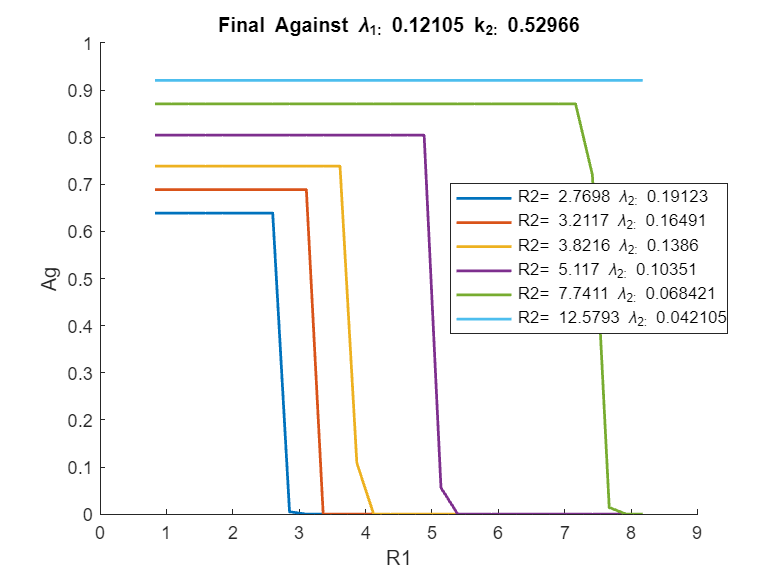

% 1,2
fig = fig+1;
figure(fig)
hold on
r1 = k1_vec./lam1_vec(d1);
for i = 1:6
    d2 = vec_R2(i);
    aga = reshape(final_Ag(:,d3,d1,d2),1,30,[]);
    zz = aga; %zz = transpose(zz);
    txt =  "R2= "+ num2str(k1_vec(d3) /lam1_vec(vec_R2(i)))+ ' \lambda_2: '+ num2str(lam1_vec(d2));
    plot(r1,zz,'LineWidth',1.5 ,'DisplayName',txt)
end
legend show
legend("Position", [0.58547,0.42327,0.35893,0.25833])
txt3 = "Final Against "+ "\lambda_1: "+ num2str(lam1_vec(d1)) +" k_2: "+ num2str(k1_vec(d3));
title(txt3)
xlabel('R1') 
ylabel('Ag') 
hold off

nexttile(2)

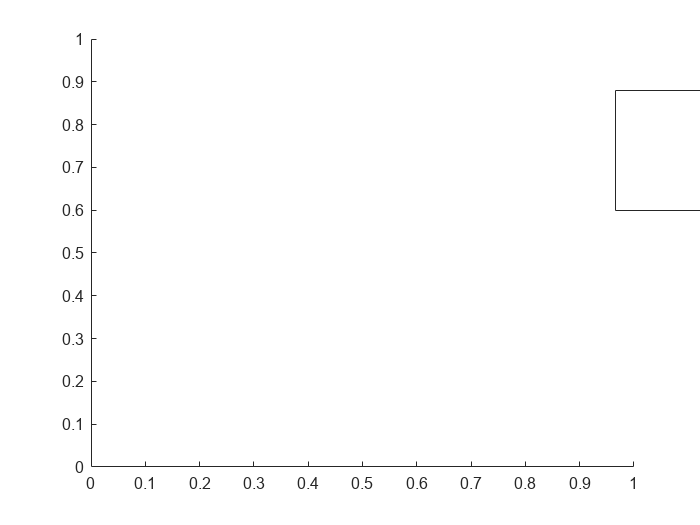

legend("Position", [0.87913,0.59867,0.33929,0.22976])

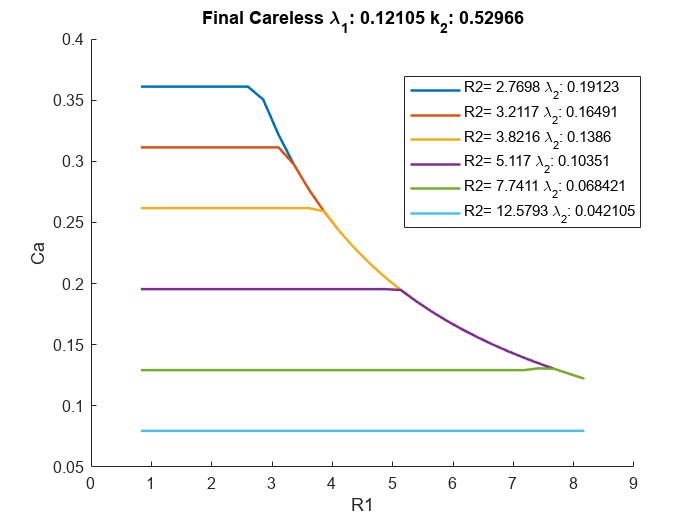

General Error occurred in WebControllerFactory::create()


% 1,3
fig = fig+1;
figure(fig)
hold on
r1 = k1_vec./lam1_vec(d1);
for i = 1:6
    d2 = vec_R2(i);
    aga = reshape(final_Ca(:,d3,d1,d2),1,30,[]);
    zz = aga; %zz = transpose(zz);
    txt =  "R2= "+ num2str(k1_vec(d3) /lam1_vec(vec_R2(i)))+ ' \lambda_2: '+ num2str(lam1_vec(d2));
    plot(r1,zz,'LineWidth',1.5 ,'DisplayName',txt)
end
legend show
txt3 = "Final Careless "+ "\lambda_1: "+ num2str(lam1_vec(d1)) +" k_2: "+ num2str(k1_vec(d3));
title(txt3)
xlabel('R1') 
ylabel('Ca') 
hold off

legend("Position", [0.57653,0.59521,0.33929,0.22976])

## Function section

function y = x_nullcline(x, k1,k2,lambda_1, lambda_2)
y = (x.*(k2-k2*x+lambda_2)-lambda_2)./(x.*(k2-k1)+(lambda_1-lambda_2));
end

function y = y_nullcline(Ca, k1,k2,lambda_1, lambda_2)
y = (Ca.*(k1-k1*Ca+lambda_1)-lambda_1)./(Ca.*(k1-k2)-lambda_1+lambda_2);
end

function y = x_nullcline2(x, k1,k2,lambda_1, lambda_2)
    R1 = k1/lambda_1; 
    y = -x - 1/R1 +1;
end

function y = y_nullcline2(x, k1,k2,lambda_1, lambda_2)
    R2 = k2/lambda_2;
    y = -x - 1/R2 +1;
end